# Convolutional Coding For Rate = 1/2 and Kc = 3

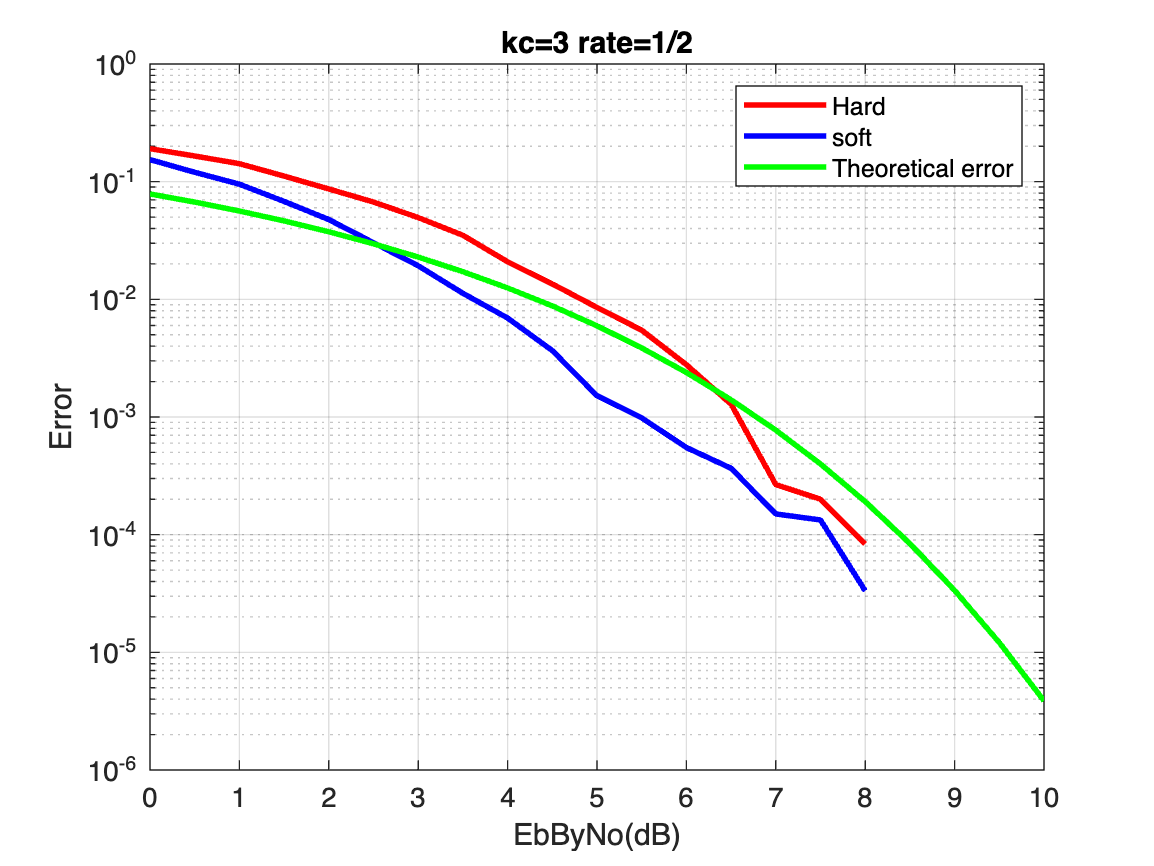


EbByNodB = 0:0.5:10;
R = 1/2;
k = 1;
n = 2;
kc = 3; 

% Generating Practical_error and Theoratical_error matrices
practical_error_Hard = zeros(1, length(EbByNodB));
practical_error_Soft = zeros(1, length(EbByNodB));
theoretical_error = zeros(1, length(EbByNodB));

Index1 = 1;
Index2 = 1;
N = 5000;

for j = EbByNodB
    EbByNo = 10^(j/10);
    std_dev = sqrt(1 / (2* R * EbByNo));
    BER = 0.5 * erfc(sqrt(1 * EbByNo));
    No_of_errors_hard = 0;
    No_of_errors_soft = 0;
    i = 1;

    while i <= N
        % Generate random message
        message = randi([0 1], 1, 10); 
        message = [message zeros(1, kc - 1)];

        enc_array = Encoder(message);  % Encoding the msg

        modulated_msg = Modulation(enc_array, std_dev);  % Modulating the msg through BPSK

        demodualted_msg = modulated_msg < 0; % Demodulating the msg

        % Call Viterbi function
        decoded_msg_hard = Hard_Decoder(demodualted_msg);
        decoded_msg_soft = Soft_Decoder(modulated_msg);

        No_of_errors_hard = No_of_errors_hard + sum(message ~= decoded_msg_hard);
        No_of_errors_soft = No_of_errors_soft + sum(message ~= decoded_msg_soft);
        i = i + 1;
    end 

    practical_error_Hard(Index1) = (No_of_errors_hard / (N*length(message)));
    practical_error_Soft(Index1) = (No_of_errors_soft / (N*length(message)));
    theoretical_error(Index2) = BER;
    Index1 = Index1 + 1;
    Index2 = Index2 + 1;
    
end

practical_error_Soft
practical_error_Hard
theoretical_error
% Ploting the Graphs for our outputs
semilogy(EbByNodB, practical_error_Hard, 'r-', 'LineWidth', 2.0);
hold on;
semilogy(EbByNodB, practical_error_Soft, 'b-', 'LineWidth', 2.0);
semilogy(EbByNodB, theoretical_error, 'g-', 'LineWidth', 2.0);
legend('Hard','soft', 'Theoretical error');
grid on;
title('kc=3 rate=1/2');

xlabel('EbByNo(dB)');
ylabel('Error');

hold off;

## Encoder Function

function observed = Encoder(inputs)
    shift_reg = [0, 0, 0];
    
    % Initialize the output observation array
    observed = zeros(1, length(inputs) * 2);
    observed_index = 1;
    
    idx = 1;

    % Iterate over input sequence using a while loop
    while idx <= length(inputs)
        % Get the input bit for the current time step
        input_bit = inputs(idx);

        % Shift the register to the left
        shift_reg(3) = shift_reg(2);
        shift_reg(2) = shift_reg(1);
        shift_reg(1) = input_bit;

        % Compute the state based on the current shift register values
        state = [shift_reg(1), shift_reg(2)];

        % Perform Viterbi encoding (Generate encoded bits based on the shift register)
        encoded_bits = [xor(xor(shift_reg(1), shift_reg(2)), shift_reg(3)), xor(shift_reg(1), shift_reg(3))];

        % Store the encoded bits in the output observation array
        observed(observed_index) = encoded_bits(1);
        observed(observed_index + 1) = encoded_bits(2);
        observed_index = observed_index + 2;

        idx = idx + 1;
    end
end




## Modulation Function


function modulated_operation = Modulation(encoded_message,std_dev)
     % BPSK modulation
     s = 1 - 2 * encoded_message; 
     modulated_operation = s + std_dev * randn(1, length(encoded_message));
end


## Hamming distance calculator


function dist = Hamming_Distance(x,y,w,z)
    dist=xor(x,w)+xor(y,z);
end


## Euclidean distance calculator Function


function dist = Euclidean_Distance(x,y,w,z)
    dist=sqrt((x-w)^2+(y-z)^2);
end


## Hard Decision Decoding Function



function decoded_msg=Hard_Decoder(observed)

st_metric = struct('zero', 0, 'one', 0, 'two', 0, 'three', 0);
state_machine = struct('zero', struct('b1', struct('out_b', [1 1], 'prev_st', 'one', 'input_b', 0), 'b2', struct('out_b', [0 0], 'prev_st', 'zero', 'input_b', 0)), 'one', struct('b1', struct('out_b', [0 1], 'prev_st', 'three', 'input_b', 0),'b2', struct('out_b', [1 0], 'prev_st', 'two', 'input_b', 0)), 'two', struct('b1', struct('out_b', [1 1], 'prev_st', 'zero', 'input_b', 1),'b2', struct('out_b', [0 0], 'prev_st', 'one', 'input_b', 1)), 'three', struct('b1', struct('out_b', [1 0], 'prev_st', 'three','input_b', 1), 'b2', struct('out_b', [0 1], 'prev_st', 'two', 'input_b', 1)));
% Trellis structure
 decoded_msg=[];
 mp = cell(1, length(observed)/2 + 1);
 mp{1} = containers.Map();
 
 for i = fieldnames(state_machine)'
    mp{1}(i{1}) = struct('metric', st_metric.(i{1}));
 end

 for j = 1:length(observed)/2
    mp{j + 1} = containers.Map();
    
    for i = fieldnames(state_machine)'
    % Check for smallest bit difference from possible previous paths, adding with previous metric
    prev_st_1 = state_machine.(i{1}).b1.prev_st;
    first_b_metric = mp{j}(prev_st_1).metric + (Hamming_Distance(state_machine.(i{1}).b1.out_b(1),state_machine.(i{1}).b1.out_b(2),observed(2*j-1),observed(2*j)));
    prev_st_2 = state_machine.(i{1}).b2.prev_st;
    second_b_metric = mp{j}(prev_st_2).metric + (Hamming_Distance(state_machine.(i{1}).b2.out_b(1),state_machine.(i{1}).b2.out_b(2),observed(2*j-1),observed(2*j)));

        if first_b_metric > second_b_metric
            mp{j + 1}(i{1}) = struct('metric', second_b_metric,'branch', 'b2');
        else
            mp{j + 1}(i{1}) = struct('metric', first_b_metric, 'branch','b1');
        end

    end

 end

 % Traceback the path on smaller metric on last trellis column
 mini = min(cellfun(@(x) x.metric, mp{end}.values));
 for i = fieldnames(state_machine)'
    if mp{end}(i{1}).metric == mini
        src_state = i{1};
        
        for j = length(observed)/2:-1:1
            branch = mp{j + 1}(src_state).branch;
            decoded_msg = [state_machine.(src_state).(branch).input_b,decoded_msg]; %Correcting the index
            src_state = state_machine.(src_state).(branch).prev_st;
        end

        break;
    end
 end

end




## Soft decision decoding function



function decoded_msg = Soft_Decoder(observed)


st_metric = struct('zero', 0, 'one', 0, 'two', 0, 'three', 0);
state_machine = struct('zero', struct('b1', struct('out_b', [-1 -1], 'prev_st', 'one', 'input_b', 0), 'b2', struct('out_b', [1 1], 'prev_st', 'zero', 'input_b', 0)), 'one', struct('b1', struct('out_b', [1 -1], 'prev_st', 'three', 'input_b', 0), 'b2', struct('out_b', [-1 1], 'prev_st', 'two', 'input_b', 0)), 'two', struct('b1', struct('out_b', [-1 -1], 'prev_st', 'zero', 'input_b', 1), 'b2', struct('out_b', [1 1], 'prev_st', 'one', 'input_b', 1)), 'three', struct('b1', struct('out_b', [-1 1], 'prev_st', 'three', 'input_b', 1), 'b2', struct('out_b', [1 -1], 'prev_st', 'two', 'input_b', 1)));

 % Trellis structure
 decoded_msg=[];
 mp = cell(1, length(observed)/2 + 1);
 mp{1} = containers.Map();
 
 for i = fieldnames(state_machine)'
 mp{1}(i{1}) = struct('metric', st_metric.(i{1}));
 end

 for j = 1:length(observed)/2
    mp{j + 1} = containers.Map();
    
    for i = fieldnames(state_machine)'
    % Check for smallest bit difference from possible previous paths, adding with previous metric
    prev_st_1 = state_machine.(i{1}).b1.prev_st;
    first_b_metric = mp{j}(prev_st_1).metric + (Euclidean_Distance(state_machine.(i{1}).b1.out_b(1),state_machine.(i{1}).b1.out_b(2),observed(2*j-1),observed(2*j)));
    prev_st_2 = state_machine.(i{1}).b2.prev_st;
    second_b_metric = mp{j}(prev_st_2).metric + (Euclidean_Distance(state_machine.(i{1}).b2.out_b(1),state_machine.(i{1}).b2.out_b(2),observed(2*j-1),observed(2*j)));

        if first_b_metric > second_b_metric
            mp{j + 1}(i{1}) = struct('metric', second_b_metric,'branch', 'b2');
        else
            mp{j + 1}(i{1}) = struct('metric', first_b_metric, 'branch','b1');
        end

    end

 end

 % Traceback the path on smaller metric on last trellis column
 mini = min(cellfun(@(x) x.metric, mp{end}.values));
 for i = fieldnames(state_machine)'
    if mp{end}(i{1}).metric == mini
        src_state = i{1};
        
        for j = length(observed)/2:-1:1
            branch = mp{j + 1}(src_state).branch;
            %Correcting the index
            decoded_msg = [state_machine.(src_state).(branch).input_b,decoded_msg]; 
            src_state = state_machine.(src_state).(branch).prev_st;
        end

        break;
    end
 end

end

